# 一、路径操作

- 显示当前所有搜索目录；

% path

- pathtool：打开设置路径对话框；

pathtool

- 将所有搜索路径链接成一个长字符串；

% genpath

- 使用path命令扩展目录；

path(path,'E:\Mygit\matlab\learning\')

- 使用addpath命令扩展目录；

addpath 'E:\Mygit\matlab\learning\' -begin

# 二、常用符号

- Esc：清除一行；

- Alt+Backspace：删除到行尾；

- ; 分号：断行或者取消显示；

- ...三个点：续行号，一行显示不完的代码，连接下一行；

- cd：显示和改变工作目录；

- clc：自动清除命令行窗口；

- clear：清除变量，clear x 清除x变量；

- clf：清除图形窗口；

# 三、运算符号

- 算数运算符

% +  ：加
% -  ：减
% *  ：乘
% /  ：右除，传统的除法，除以；\ 左除，和传统的除法相反；
% ^  ：乘方
% .* ：点乘，矩阵内元素对元素的运算，其它点运算的含义类似，.^,.\等；
% '  ：矩阵转置，当矩阵是复数时，求矩阵的共轭转置；
% .' ：点转置，当矩阵是复数时，不求矩阵的共轭；

- 关系运算符          

% ==：等于
% ~=：不等于
% >,>=,<,<=：大于，大于等于，小于，小于等于；  

- 逻辑运算符

% &或者and：与
% |或者or ：或
% ~或者not：非
% xor：逻辑异或，两个操作之一为非零值时，结果为1，否则为0；
% any：有非零元素则为1；
% all：所有元素为非零则为1；

- 复数运算

% abs：模
% angle：复数的相角；
% complex：用实部和虚部构造一个复数；
% conj：复数的共轭；
% imag：复数的虚部；
% real：复数的实部；
% unwrap：调整矩阵元素的相位；
% isreal：是否为实数矩阵；
% cplxpair:把复数矩阵排列成复共轭对。

# 四、向量和多项式

## 4.1 向量

- 行向量

a = [2 4 6 8]

a =      2     4     6     8


- 列向量

b = [2;4;6;8]

b =      2
     4
     6
     8


- 冒号创建行向量

c = 0:2:10 % 0开始，10结束，增量为2；

c =      0     2     4     6     8    10


d = linspace(0,10,5) % 0开始，10结束，5个元素；

d =          0    2.5000    5.0000    7.5000   10.0000


e = logspace(1,5,5) %10的1次方开始，10的3次方结束，5个元素；

e =           10         100        1000       10000      100000


- 向量的运算

% 点积：|a|*|b|*cos(θ)是一个标量
dot(a,b) % 等价于：

ans = 120

a*b

ans = 120

% 叉积：|a|*|b|*sin(θ)，方向由右手法则来定义，是一个向量；且a,b必须为三维向量；

[叉积](https://blog.csdn.net/hc14519/article/details/50716299?utm_medium=distribute.pc_relevant_t0.none-task-blog-BlogCommendFromMachineLearnPai2-1.control&depth_1-utm_source=distribute.pc_relevant_t0.none-task-blog-BlogCommendFromMachineLearnPai2-1.control)

a = [1 2 3]

a =      1     2     3


b = [1 -1 2]

b =      1    -1     2


cross(a,b)

ans =      7     1    -3


## 4.2 多项式

- 多项式系数和向量是一一对应的关系；

- 从最高次项到常数项，系数为零不能省略；

'a*x^n+b*x^(n-1)' % 1,

ans = 'a*x^n+b*x^(n-1)'

p = [1 2 3  0 4]

p =      1     2     3     0     4


poly2sym(p)

$$ans = x^{4}+2\,x^{3}+3\,x^{2}+4$$

### 4.2.1 多项式四则运算

- 乘法运算：用函数conv(p1,p2)来实现，相当于执行两个数组的卷积；

p1 = (1:5);
p2 = (2:6);
p3 = conv(p1,p2)

p3 =      2     7    16    30    50    58    58    49    30


poly2sym(p1)

$$ans = x^{4}+2\,x^{3}+3\,x^{2}+4\,x+5$$

poly2sym(p2)

$$ans = 2\,x^{4}+3\,x^{3}+4\,x^{2}+5\,x+6$$

poly2sym(p3)

$$ans = 2\,x^{8}+7\,x^{7}+16\,x^{6}+30\,x^{5}+50\,x^{4}+58\,x^{3}+58\,x^{2}+49\,x+30$$

- 除法运算：使用deconv(p1,p2)来实现，相当于求两个数组的解卷；

p4 = deconv(p1,p2)

p4 = 0.5000

poly2sym(p4)

$$ans = \frac{1}{2}$$

### 4.2.2 多项式导数运算

- 多项式倒数用函数polyder()来实现：

p = [2 3 8 -5 6]

p =      2     3     8    -5     6


poly2sym(p)

$$ans = 2\,x^{4}+3\,x^{3}+8\,x^{2}-5\,x+6$$

q = polyder(p)

q =      8     9    16    -5


poly2sym(q)

$$ans = 8\,x^{3}+9\,x^{2}+16\,x-5$$

## 4.3 特殊变量

### 4.3.1 单元型变量

- 以单元为元素的数组，每个元素称为单元，每个单元可以包含其他类型的数组，如实数矩阵、字符串、复数向量，由{}创建，其数据通过数组下标来引用：

- 有两种定义方式：

- 1、赋值语句直接定义；

A = [1 2;3 4];
B = 3+2*1i;
C = 'efg';
D = 2;
E = {A,B;C,D}
celldisp(E)

 
E{1,1} =
 
     1     2
     3     4

 
 
E{2,1} =
 
efg
 
 
E{1,2} =
 
   3.0000 + 2.0000i

 
 
E{2,2} =
 
     2

 


- 2、由函数cell()预先分配存储空间，然后对单个元素逐个赋值。

E = cell(1,3);
E{1,1} = (1:4);
E{1,2} = 3+2*1i;
E{1,3} = 2;

- 单元型变量的引用

E{1} %显示具体值；

ans =      1     2     3     4


E(1) %显示压缩形式；

ans = 1×1 cell 数组
    {1×4 double}


- 单元型变量的函数：celldisp(),cellplot()等；

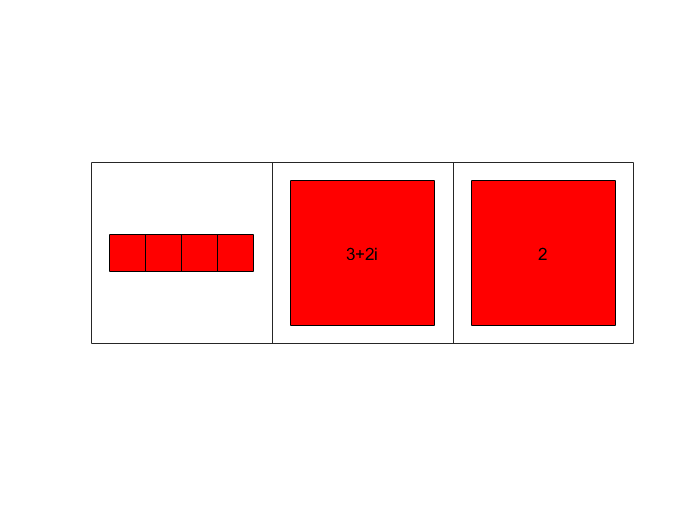

cellplot(E) %以图形化显示单元型变量；

### 4.3.2 结构型变量

- 结构型变量是根据属性名（field）组织起来的不同数据类型的集合。使用struct()函数创建，类似于键值对儿。

mn = struct('color',{'red','black'},'number',{1,2})

mn = 包含以下字段的 1×2 struct 数组:
    color
    number


mn(1)

ans = 包含以下字段的 struct :
     color: 'red'
    number: 1


mn(2)

ans = 包含以下字段的 struct :
     color: 'black'
    number: 2


mn(2).color

ans = 'black'

- 结构型变量的函数

struct：创建结构型变量

fieldnames：得到结构型变量的属性名

getfield：得到结构型变量的属性值

setfield：设定结构型变量的属性值

rmfield：删除结构型变量的属性

isfield：判断是否为结构型变量的属性

isstruct：判断是否为结构型变量

# 五、矩阵运算

## 5.1 矩阵

### 5.1.1  矩阵的构成

- 由中括号标识；

- 逗号或空格分隔；

- 分号换行；

### 5.1.2 矩阵的创建

- 直接输入；

- M文件输入；

- 直接load文本文件；

### 5.1.3 创建特殊矩阵

- eye(n)：创建$n \times n$单位矩阵；

- eye(m,n)

- eye(size(A))：创建与A矩阵维数相同的单位矩阵；

- ones(n)：创建全为1的$n \times n$矩阵；

- rand(n)：创建[0,1]均匀分布的随机矩阵；

- compan(P)：P的伴随矩阵；

- diag(V)：创建以向量V中的元素为对角的对角矩阵；

- hilb(n)：创建$n \times n$Hilbert矩阵，高度病态（即，任何一个元素发生一点变动，整个矩阵的行列式的值和逆矩阵都会发生巨大变化），病态程度和阶数相关.$A(i,j) = 1/(i+j-1)$.

- magic(n)：创建$n \times n$魔方矩阵，是有相同的行数和列数，并在每行每列、对角线上的和都相等的矩阵。

- sparse(A)：将矩阵A转化为稀疏矩阵形式，矩阵中非零元素的个数远远小于矩阵元素的总数，并且非零元素的分布没有规律，通常认为矩阵中非零元素的总数比上矩阵所有元素总数的值小于等于0.05时，则称该矩阵为稀疏矩阵(sparse matrix)

## 5.2 矩阵元素的运算

### 5.2.1矩阵元素的修改

- $D = [A;B\quad C]$ 扩充矩阵

A = [1 2 3;4 5 6];
B = eye(2);
C = zeros(2,1);
D = [A;B C]

D =      1     2     3
     4     5     6
     1     0     0
     0     1     0


- $A(m,:)=[]$删除第m行；

- $A(:,n)=[]$删除第n列；

- $A(m,n)=a$对矩阵A的第m行第n列的元素赋值；

- $A(m,:)=[a ,b \cdots]$对矩阵m行赋值。

### 5.2.2 矩阵的变维

- reshape()函数；

A = 1:12;
reshape(A,3,4)

ans =      1     4     7    10
     2     5     8    11
     3     6     9    12


### 5.2.3 矩阵的旋转

- rot90(A)：将A逆时针旋转90度；

- rot90(A,k)：将A逆时针旋转90*k度，k为正或负整数；

- fliplr(X)：将X左右翻转；

- flipud(X)：将X上下翻转；

- flipdim(X,dim)：dim = 1对行翻转，dim = 2对列翻转；

### 5.2.4 矩阵的抽取

- diag(X,k)：抽取X的第k条对角线上的元素向量，k为正，上面第k条对角线，k为负，下面数第k条对角线；

X = magic(5)

X =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


V1 = diag(X,2)

V1 =      1
    14
    22


V2 = diag(X,-2)

V2 =      4
    12
    25


V3 = diag(X) % X为矩阵，则抽取主对角线；

V3 =     17
     5
    13
    21
     9


diag(V3) % V3为向量，以V3向量为对角元素生成对角矩阵；

ans =     17     0     0     0     0
     0     5     0     0     0
     0     0    13     0     0
     0     0     0    21     0
     0     0     0     0     9


- tril(X)：X的下三角矩阵；

- tril(X,k)：X的第k条对角线下面的部分；

- triu(X)：X的上三角矩阵；

- triu(X,k)：X的第k条对角线上面的部分；

## 5.3 矩阵数学运算

### 5.3.1 矩阵的加法

- 对应元素相加；

- 满足交换律和结合律；

### 5.3.1 矩阵的减法

- 对应元素相减；

### 5.3.3 矩阵的乘法

- 
$$AB \neq BA$$


- $A.*B$：点乘运算，对应元素相乘；

### 5.3.4 矩阵的除法

- 左除：$D*X=B \Rightarrow X = D^{-1}*B=D \backslash B$，分母在左边：

A = [1 2 3;0 3 3;7 9 5]

A =      1     2     3
     0     3     3
     7     9     5


B = [8 3 9;2 8 1;3 9 1]

B =      8     3     9
     2     8     1
     3     9     1


A.\B %点左除，分母在左边；

ans =     8.0000    1.5000    3.0000
       Inf    2.6667    0.3333
    0.4286    1.0000    0.2000


- 右除：$X*A=B \Rightarrow X=B*A^{-1} = B/A$，分母在右边，更像我们常用的除法：

A = [1 2 3;5 8 6]

A =      1     2     3
     5     8     6


B = [3 2 1;2 4 3]

B =      3     2     1
     2     4     3


A./B

ans =     0.3333    1.0000    3.0000
    2.5000    2.0000    2.0000


## 5.4 矩阵运算

### 5.4.1 幂运算

- 将矩阵中的每个元素进行乘方运算；

-  符号：.^

- $A^kA^l=A^{k+l},(A^k)^l=A^{kl}$，但是，$(AB)^k \neq A^kB^k$

A = [1 2 3;0 3 3;7 9 5]

A =      1     2     3
     0     3     3
     7     9     5


A.^2

ans =      1     4     9
     0     9     9
    49    81    25


### 5.4.2 矩阵的逆

A = rand(3)

A =     0.0975    0.9575    0.9706
    0.2785    0.9649    0.9572
    0.5469    0.1576    0.4854


inv(A)

ans =    -4.7518    4.6665    0.2997
   -5.8117    7.2362   -2.6485
    7.2412   -7.6076    2.5827


### 5.4.3 矩阵的条件数

- 方程组$AX=b$的解X对A和b的误差（发生较小变动）的敏感程度；

- 远大于1是“病态”，否则为“良态”。

A = [1 5 -3 4;9 -1 2 1;-2 6 8 5;7 1 0 1]

A =      1     5    -3     4
     9    -1     2     1
    -2     6     8     5
     7     1     0     1


cond(A)

ans = 17.5585

## 5.5 矩阵分解

### 5.5.1 Cholesky分解

A = [1 1 1 1;1 2 3 4;1 3 6 10;1 4 10 20]

A =      1     1     1     1
     1     2     3     4
     1     3     6    10
     1     4    10    20


chol(A)

ans =      1     1     1     1
     0     1     2     3
     0     0     1     3
     0     0     0     1


[R,p] = chol(A)

R =      1     1     1     1
     0     1     2     3
     0     0     1     3
     0     0     0     1


p = 0

### 5.5.2 LU分解

- 
$$A=LU$$


[B,C] = lu(A)

B =     1.0000         0         0         0
    1.0000    0.3333    1.0000         0
    1.0000    0.6667    1.0000    1.0000
    1.0000    1.0000         0         0


C =     1.0000    1.0000    1.0000    1.0000
         0    3.0000    9.0000   19.0000
         0         0   -1.0000   -3.3333
         0         0         0   -0.3333


- 
$$PA=LU$$


[L,U,P] = lu(A)

L =     1.0000         0         0         0
    1.0000    1.0000         0         0
    1.0000    0.3333    1.0000         0
    1.0000    0.6667    1.0000    1.0000


U =     1.0000    1.0000    1.0000    1.0000
         0    3.0000    9.0000   19.0000
         0         0   -1.0000   -3.3333
         0         0         0   -0.3333


P =      1     0     0     0
     0     0     0     1
     0     1     0     0
     0     0     1     0


### 5.5.3 $LDM^T$和$LDL^T$分解

## 5.5 矩阵分解